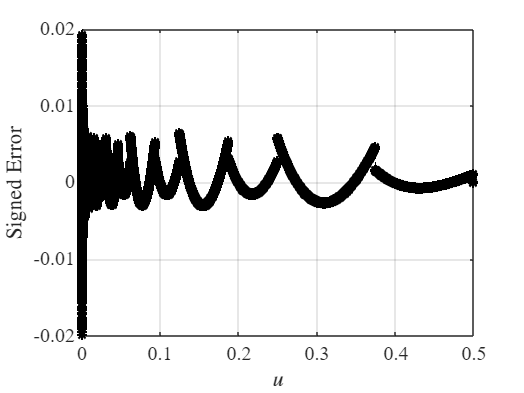

%% Method 3: Piecewise Linear Approximation on Super-dyadic Intervals
%(instead of successive intervals of 2 like the dyadic, we now use \sqrt(2)

clear; clc;

d              = 14;      
Nhalf          = 2^(d-1);                     
u_edges        = (0:Nhalf)/2^d;               
nSamplesPerBin = 50;                          
delta          = 1e-12;                       
du             = 2^(-d);

Z_ave  = arrayfun(@(u1,u2) norminv_int(u1,u2)/du, u_edges(1:end-1), u_edges(2:end));
Z2_ave = arrayfun(@(u1,u2) norminv2_int(u1,u2)/du, u_edges(1:end-1), u_edges(2:end));

use_superdyadic = true;  % false for piecewise dyadic

Z2 = Z_ave; 
if use_superdyadic
    % Super-dyadic
    N = Nhalf;
    n_subs = [];
    total = 0;
    lvl = 1;
    while total < N
        n_this = 2^floor((lvl-1)/2);
        if total + n_this > N
            n_this = N - total;
        end
        n_subs = [n_subs, n_this];
        total = total + n_this;
        lvl = lvl + 1;
    end
    idx = 1;
    for k_lvl = 1:length(n_subs)
        n_sub = n_subs(k_lvl);
        k2 = idx:(idx + n_sub - 1);

        Z_ave2 = mean(Z_ave(k2));
        dn = (1:n_sub) - (n_sub+1)/2;
        dZ = Z_ave(k2) - Z_ave2;
        if sum(dn.^2) == 0
            dZslope = 0;
        else
            dZslope = (dZ * dn') / (dn * dn');
        end
        Z2(k2) = Z_ave2 + dn * dZslope;

        idx = idx + n_sub;
    end
    method_title = 'Super-Dyadic Piecewise Linear';
else
    % Dyadic
    for k = 1:d-1
        if k==1 
            n_sub = 2;
            k2 = 1:2;
        else
            n_sub = 2^(k-1);
            k2 = (n_sub+1):2*n_sub;
        end
        Z_ave2 = sum(Z_ave(k2))/n_sub;
        dn = (1:n_sub) - (n_sub+1)/2;
        dZ = Z_ave(k2) - Z_ave2;
        dZ = (dZ*dn') / (dn*dn');
        Z2(k2) = Z_ave2 + dn*dZ;
    end
    method_title = 'Dyadic Piecewise Linear';
end

% Plotting
all_u    = [];
all_err  = [];
maxErr   = zeros(1, Nhalf);

for j = 1:Nhalf
    uL = u_edges(j)   + delta;
    uR = u_edges(j+1) - delta;
    us = linspace(uL, uR, nSamplesPerBin);
    qs = sqrt(2)*erfinv(2*us - 1);    

    errs = Z2(j) - qs;

    all_u   = [all_u,   us];
    all_err = [all_err, errs];

    maxErr(j)   = max(abs(errs));
end

maxZ         = max(abs(Z2));
u_mid = (u_edges(1:end-1) + u_edges(2:end))/2;

theoretical_MSE = mean(Z2_ave - 2*Z2.*Z_ave + Z2.^2);


% Signed Error Plot
figure;
plot(all_u, all_err, 'k', 'LineWidth', 1.2);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Signed Error', 'Interpreter', 'latex');
ylim([-0.02, 0.02]);
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

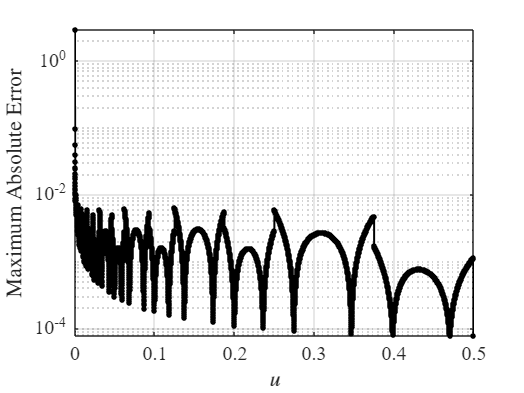

set(gcf, 'Color', 'w');


% Max Absolute Error Plot
figure;
semilogy(u_mid, maxErr, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Maximum Absolute Error', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

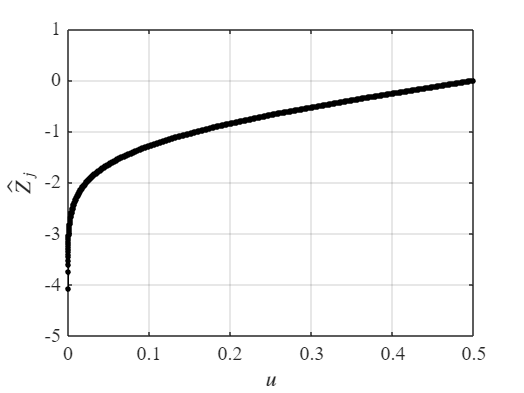

set(gcf, 'Color', 'w');


% LUT Approximation
figure;
plot(u_mid, Z2, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('$\hat Z_j$', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

set(gcf, 'Color', 'w');

fprintf('d: %d\n', d);

d: 14


fprintf('MSE over [0,0.5]: %.3e\n', theoretical_MSE);

MSE over [0,0.5]: 1.012e-05


fprintf('Maximum absolute LUT value: %.6f\n', maxZ);

Maximum absolute LUT value: 4.075145



%% Obtaining LUT Array: Optimal coefficeints (a,b)
idx = 2*d:-1:2

idx =     28    27    26    25    24    23    22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2


grid_idx =round(2^d*2.^(-idx/2))

grid_idx =            1           1           2           3           4           6           8          11          16          23          32          45          64          91         128         181         256         362         512         724        1024        1448        2048        2896        4096        5793        8192


superdyadic_points=2.^(-idx/2)

superdyadic_points =     0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0007    0.0010    0.0014    0.0020    0.0028    0.0039    0.0055    0.0078    0.0110    0.0156    0.0221    0.0312    0.0442    0.0625    0.0884    0.1250    0.1768    0.2500    0.3536    0.5000




grid_vals = Z2(grid_idx);

delta_x = diff(superdyadic_points);
delta_y = diff(grid_vals);         
b = delta_y ./ delta_x;           
a = grid_vals(1:end-1) - b .* superdyadic_points(1:end-1);  

LUT = [a(:), b(:)]

LUT = 1.0e+03 *

   -0.0041         0
   -0.0049    9.2122
   -0.0041    2.6357
   -0.0038    1.2447
   -0.0038    1.2079
   -0.0036    0.5850
   -0.0036    0.4871
   -0.0035    0.3943
   -0.0034    0.2797
   -0.0032    0.1833


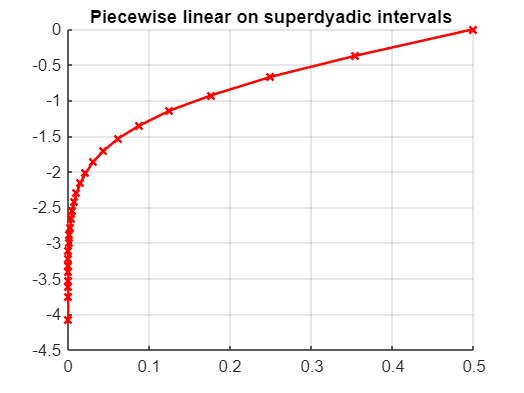


figure
grid on
title("Piecewise linear on superdyadic intervals")
hold on
for i = 1:length(b)
    xx = linspace(superdyadic_points(i), superdyadic_points(i+1), 2);
    yy = a(i) + b(i)*xx;
    plot(xx, yy, '-xr', 'LineWidth', 1.5);
end




%%Saving as a cpp array (.h file)
headerFile = 'superdyadic_lut_52.h';
fid = fopen(headerFile,'w');

fprintf(fid, '// superdyadic_lut_52.h\n');
fprintf(fid, '#pragma once\n\n');

%FP32
fprintf(fid, 'inline constexpr float SUPERDYADIC_LUT_A_FP32[26] = { ');
for i=1:26
    fprintf(fid, '%0.8gf', a(i));
    if i<26, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n');
fprintf(fid, 'inline constexpr float SUPERDYADIC_LUT_B_FP32[26] = { ');
for i=1:26
    fprintf(fid, '%0.8gf', b(i));
    if i<26, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n\n');

%FP16
fprintf(fid, 'inline constexpr _Float16 SUPERDYADIC_LUT_A_FP16[26] = { ');
for i=1:26
    fprintf(fid, '%g', a(i));
    if i<26, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n');
fprintf(fid, 'inline constexpr _Float16 SUPERDYADIC_LUT_B_FP16[26] = { ');
for i=1:26
    fprintf(fid, '%g', b(i));
    if i<26, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n\n');

fprintf(fid, '// Superdyadic interval endpoints on [0, 0.5]\n');
fprintf(fid, 'static constexpr float SUPERDYADIC_U[%d] = { ', numel(superdyadic_points));
fprintf(fid, '%.8gf, ', superdyadic_points);  
fprintf(fid, '};\n');


fclose(fid);





% Local functions
function y = norminv_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = normpdf(z1) - normpdf(z2);
end

function y = norminv2_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = z1.*normpdf(z1) - z2.*normpdf(z2) + (u2-u1);
end
